## Setup 

Fs0 = 48000;                 % samples per second
dt = 1/Fs0;                   % seconds per sample
StopTime = 7;             % seconds
t = (0:dt:StopTime)';     % seconds

%Sine wave:
Fc = 5000;                     % hertz
x = sin(2*pi*Fc.*t);

%Play sound
sound(x,48000);
audiowrite('teamann-sinetone.wav',[x,t],48000)

%Plot Spectrogram
title('5000 Hz Tone at 48000 samples/s');
spectrogram(x,'yaxis', kaiser(256,5),128,[], 48000);
zoom xon;

## Chirp Signal 

clc;clear all;
Fs = 48000;                 % samples per second
dt = 1/Fs;                   % seconds per sample
StopTime1 = 7;             % seconds
t1 = (0:dt:StopTime1)';     % seconds
f=(0:4000/(Fs*StopTime1):4000)';%# of times f fits in interval 
%Sine wave:
x1 = sin(2*pi.*t1.*f);% second input originally at 0
%plot(t,y)
spectrogram(x1,'yaxis', kaiser(256,5),128,[], 48000);
title('8000 Hz Chirp at 7s');
ylim([0 10]);
zoom xon;

%Play sound
sound(x1,Fs);
audiowrite('teamann-chirp.wav',[x1,t1],48000);

%Plot Spectrogram
spectrogram(x1,'yaxis', kaiser(256,5),128,[], 48000);
title('8000 Hz Chirp at 7s');
ylim([0 10]);
zoom xon;

## Sine Tone Fun 

Fs = 48000;                 % samples per second
dt = 1/Fs;                  % seconds per sample

% a4# Note 1:
Fc1 = 466.16;                     % hertz
time1 = (0:dt:0.5)';                    %s
x1 = sin(2*pi*Fc1.*time1);
% c5 Note 2:
Fc2 = 523.25;                     % hertz
time2 = (0.5:dt:0.75+0.5)';
x2 = sin(2*pi*Fc2.*time2);
%Sine wave for Note 3:
Fc3 = 415.3;                     % hertz
time3 = (1.25:dt:1+1.25)';
x3 = sin(2*pi*Fc3.*time3);
%Sine wave for Note 4:
Fc4 = 233.08;                     % hertz
time4 = (2.25:dt:2.25+0.75)';
x4 = sin(2*pi*Fc4.*time4);
%Sine wave for Note 5:
Fc5 = 311.13;                     % hertz
time5 = (3.0:dt:3.0+2.0)';
x5 = sin(2*pi*Fc5.*time5);
%concatenate arrays into one
z = [x1;x2;x3;x4;x5];
t1 = (0:1:240004)';

%Play sound
sound(z,48000);

audiowrite('teamann-cetk.wav',[z,t1],48000);

%Plot Spectrogram
spectrogram(z,'yaxis', kaiser(256,5),128,[], 48000);
title('CETK Sine Tone');
ylim([0 2]);

## Combining Sound Files

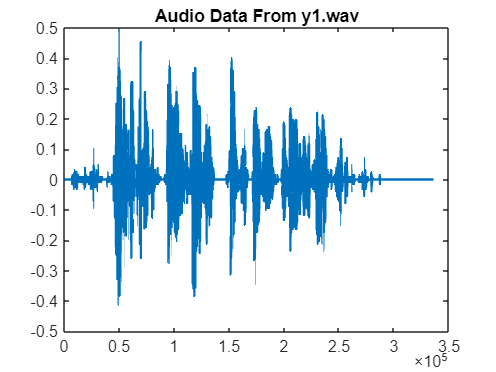

clear all;
Fs0 = 48000;                 % samples per second
dt = 1/Fs0;                   % seconds per sample
StopTime = 7;             % seconds
t = (0:1/Fs0:StopTime)';     % seconds

%create 5000Hz Sine wave:
Fc = 5000;                     % hertz
x = sin(2*pi*Fc.*t);

% Import audio
[data, fs] = audioread("C:\Users\Tooxie\Documents\MATLAB\y1.wav");

% Display results
plot(data, "LineWidth", 1.5);
title("Audio Data From y1.wav");

legend;

%data is clipped in matlab pad the data at end iwth zeros
lentopad = length(t)-length(data);
padarr = zeros(1,1);
data0 = cat(1,data,padarr);
%add sine and padded data together
combined = x + data0;

%Play sound
sound(combined,fs);

%write/read audio back
audiowrite('teamann-speechchirp.wav',combined,48000);

[val,fs] = audioread('teamann-speechchirp.wav');

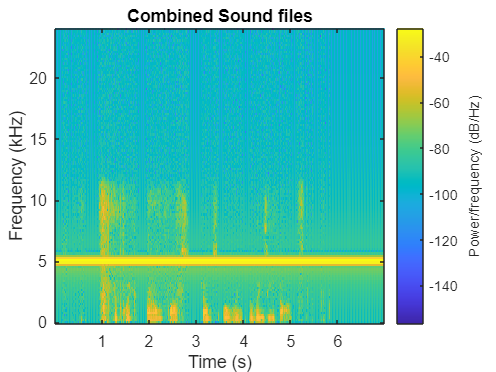

%Plot Spectrogram
spectrogram(combined,'yaxis', kaiser(256,5),128,[], 48000);
title('Combined Sound files');
%spectrogram(data,'yaxis', kaiser(256,5),128,[], 48000);
xlim([0.00 7.00])
zoom xon;

## Speech and Audio Filtering 

%make Filter and output to y
[y,b] = lowpass(combined,4000,48000,ImpulseResponse="iir",Steepness = 0.95);

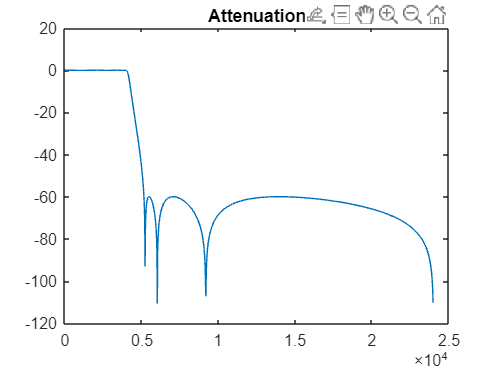

%Check frequency response
[h1,filt] = freqz(b,1024,fs);
plot(filt,mag2db(abs(h1)));
title('Attenuation');

%fpass = [1,3000];
%y = bandpass(combined,fpass,48000);

%play sound
sound(y,fs);

%Write to wav file
audiowrite('teamann-filteredspeechsine.wav',[y,t],48000);

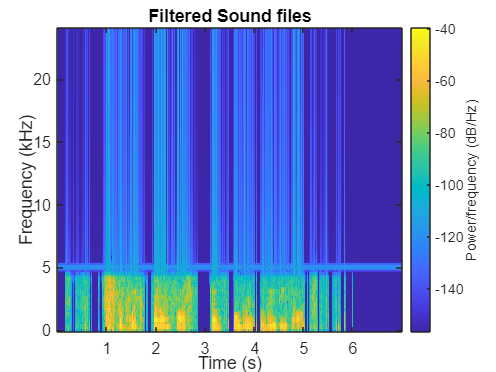

%Plot Spectrogram
spectrogram(y,'yaxis', kaiser(256,5),128,[], 48000);
title('Filtered Sound files');
xlim([0.00 7.00])
%ylim([0 600])
zoom xon;

## Stereo fun

%Write to a wav file
audiowrite('teamann-stereospeechsine.wav',[data0,combined],48000);

sound([data0,combined],fs);

%Plot Spectrogram left channel
spectrogram(data0,'yaxis', kaiser(256,5),128,[], 48000);
title('Left Channel of Stereo Signal');
xlim([0.00 7.00])
%ylim([0 600])
zoom xon;

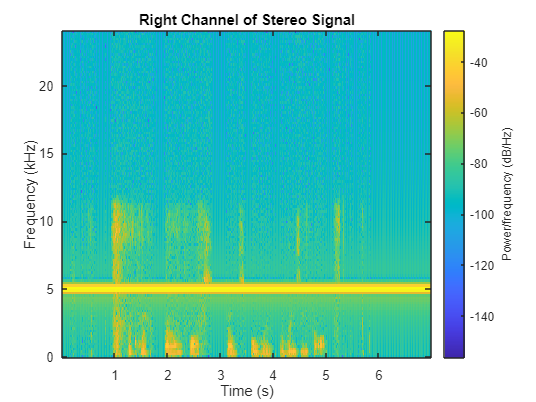

%Plot Spectrogram right channel
spectrogram(combined,'yaxis', kaiser(256,5),128,[], 48000);
title('Right Channel of Stereo Signal');
xlim([0.00 7.00])
%ylim([0 600])
zoom xon;